# レギュラーシーズンのMasseyレーティングからプレイオフを予測する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');
seasonStartYearVals=unique(tbl_results.SeasonStartYear);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByWins=[];      %勝率で予測した予測正解数
CorrectsByScoreRatio=[];    %得点割合で予測した予測正解数
CorrectsByMassey=[];    %Masseyレーティングで予測した予測正解数

シーズン開始年を指定しそれぞれについて処理を行う．

for seasonStartYearVal=seasonStartYearVals'
    ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
    tbl_teams_tmp=tbl_teams(ind,:);
    numTeams=size(unique(tbl_teams_tmp.TeamName),1);

試合は訓練用(train)とテスト用(test)に分ける

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.isRegular;
    tbl_results_train=tbl_results(ind,:);

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.isPlayoff;
    tbl_results_test=tbl_results(ind,:);

### 比較のために勝敗や得失点も集計する

勝，負試合数，および得失点を集計する

集計用の変数を準備する

    Wins=zeros(size(tbl_teams_tmp,1),1);
    Loses=zeros(size(tbl_teams_tmp,1),1);
    ScoresFor=zeros(size(tbl_teams_tmp,1),1);
    ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

    for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

        TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

        ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
        ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
        ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
        ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

        if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
            Wins(TeamANum)=Wins(TeamANum)+1;
            Loses(TeamBNum)=Loses(TeamBNum)+1;
        elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
            Loses(TeamANum)=Loses(TeamANum)+1;
            Wins(TeamBNum)=Wins(TeamBNum)+1;
        end
    end

勝率，得点割合の列を追加する

    WinRatio=Wins./(Wins+Loses);
    ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
    tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio);

勝率→得失点割合の優先順でソートし，その順位を追加する

    tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
    RankByWins=(1:size(tbl_teams_tmp,1))';
    tbl_teams_tmp=addvars(tbl_teams_tmp,RankByWins);

得失点割合→勝率の優先順でソートし，その順位を追加する

    tbl_teams_tmp=sortrows(tbl_teams_tmp,{'ScoreRatio','WinRatio'},'descend');
    RankByScoreRatio=(1:size(tbl_teams_tmp,1))';
    tbl_teams_tmp=addvars(tbl_teams_tmp,RankByScoreRatio);

### Masseyレーティングを算出する

    X=zeros(size(tbl_results_train,1), size(tbl_teams_tmp,1));  %
    y=zeros(size(tbl_results_train,1),1);
    for n1=1:size(tbl_results_train,1)
        TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));
        ScoreA=tbl_results_train.HomeScore(n1);
        ScoreB=tbl_results_train.AwayScore(n1);
        X(n1,TeamANum)=1;X(n1,TeamBNum)=-1;
        y(n1)=ScoreA-ScoreB;
    end

    RatingMassey=pinv(X)*y;
    tbl_teams_tmp=addvars(tbl_teams_tmp, RatingMassey);

プレイオフの結果を予測する

予測と実際の結果を格納する変数を定義する

    PredictionByWin=zeros(size(tbl_results_test,1),1);
    PredictionByScoreRatio=zeros(size(tbl_results_test,1),1);
    PredictionByMassey=zeros(size(tbl_results_test,1),1);
    ActualWin=zeros(size(tbl_results_test,1),1);
    plotData=[];
    for n1=1:size(tbl_results_test,1)
        if tbl_results_test.HomeScore(n1)>tbl_results_test.AwayScore(n1)
            ActualWin(n1)=1;    %ホーム勝利を1と定義する
        else
            ActualWin(n1)=0;
        end

        TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test.Away(n1));
        TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
        TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
        if TeamARank<TeamBRank
            PredictionByWin(n1)=1;
        else
            PredictionByWin(n1)=0;
        end

        TeamARank=tbl_teams_tmp.RankByScoreRatio(TeamANum);
        TeamBRank=tbl_teams_tmp.RankByScoreRatio(TeamBNum);
        if TeamARank<TeamBRank
            PredictionByScoreRatio(n1)=1;
        else
            PredictionByScoreRatio(n1)=0;
        end

        TeamAMassey=tbl_teams_tmp.RatingMassey(TeamANum);
        TeamBMassey=tbl_teams_tmp.RatingMassey(TeamBNum);
        if TeamAMassey>TeamBMassey
            PredictionByMassey(n1)=1;
        else
            PredictionByMassey(n1)=0;
        end
    end


予測正解を判定する．

    isPredictionCorrectByWins= ActualWin==PredictionByWin;
    isPredictionCorrectByScoreRatio= ActualWin==PredictionByScoreRatio;
    isPredictionCorrectByMassey= ActualWin==PredictionByMassey;

予測正解数などを保存する

    PredictedMatches=[PredictedMatches;size(tbl_results_test,1)];
    CorrectsByScoreRatio=[CorrectsByScoreRatio; sum(isPredictionCorrectByScoreRatio)];
    CorrectsByWins=[CorrectsByWins; sum(isPredictionCorrectByWins)];
    CorrectsByMassey=[CorrectsByMassey; sum(isPredictionCorrectByMassey)];
end

図示する

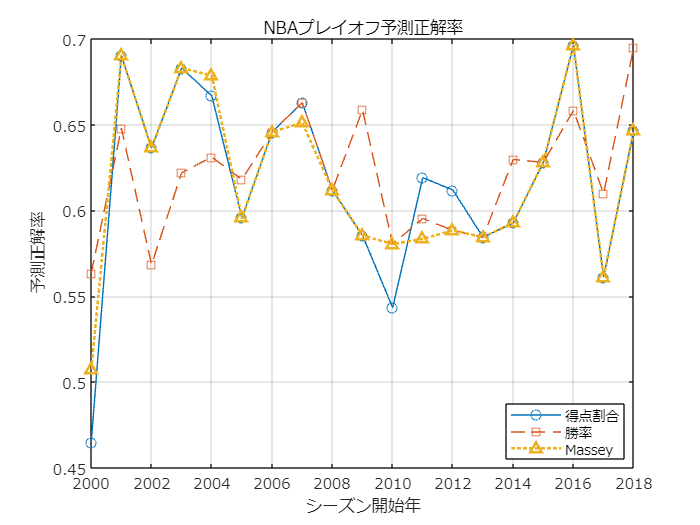

figure;
plot(seasonStartYearVals, CorrectsByScoreRatio./PredictedMatches,'o-');
hold on;grid on;
plot(seasonStartYearVals, CorrectsByWins./PredictedMatches,'s--');
plot(seasonStartYearVals, CorrectsByMassey./PredictedMatches,'^:','LineWidth',1.5);
set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('予測正解率');
legend({'得点割合','勝率','Massey'},'Location','best');
title('NBAプレイオフ予測正解率');
exportgraphics(gcf,'fig_NBAPredictionPerformanceByYear_Massey.pdf');

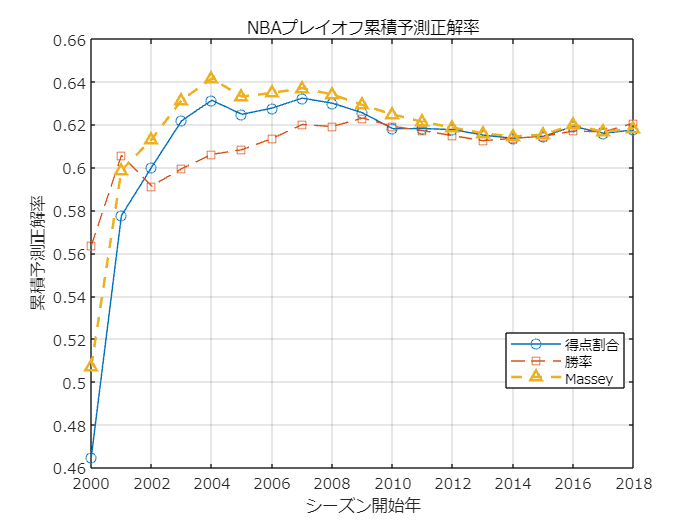

figure;
plot(seasonStartYearVals,cumsum(CorrectsByScoreRatio)./cumsum(PredictedMatches),'o-');
hold on;grid on;
plot(seasonStartYearVals, cumsum(CorrectsByWins)./cumsum(PredictedMatches),'s--');
plot(seasonStartYearVals, cumsum(CorrectsByMassey)./cumsum(PredictedMatches),'^--','LineWidth',1.5);
set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('累積予測正解率');
legend({'得点割合','勝率','Massey'},'Location','best');
title('NBAプレイオフ累積予測正解率');
exportgraphics(gcf,'fig_NBAPredictionCumSumByYear_Massey.pdf');